# TD Analyse spectrale


close all
clear all


On considère une sinusoide de fréquence f0 échantillonnée avec une fréquence d'échantillonnage fe et tronquée (N points), ce qui revient dans le domaine temporel à considérer une sinusoide (à support temporel illimité) multipliée par une fenêtre rectangulaire (de largeur N points)

## Analyse temporelle du signal

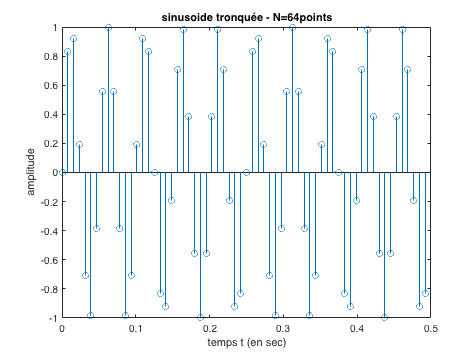

f0=20; % freq. du sinus
N=64; % nb points temporels
fe=128; % freq. d'échantillonnage du signal
Te=1/fe; % periode d'échantillonage
k=0:N-1; % indice temporel
t=k*Te; % temps

x=sin(2*pi*f0*t); % sin tronquée = sin x rect (N points)

figure
stem(t,x)
title(['sinusoide tronquée - N=',num2str(N),'points'])
xlabel('temps t (en sec)')
ylabel('amplitude')

## Analyse spectrale (N=Nf)

Dans le domaine fréquentielle, le TF de ce signal est égale à TF de la sinusoide (à support temporel illimité) convoluée avec la TF de la fenêtre rectangulaire. Comme la TF de la sinusoide est 2 impulsions de Dirac en -f0 et f0, la TF de x est egale à la somme de la TF de la fenêtre rectangulaire décalée en -f0 et en f0.

Remarques : 

1) Le signal temporel est échantillonné à la fréquence d'échan. fe (période d'échan. Te), donc le spectre est périodique de période fe. Le spectre est affiché uniquement pour f entre 0 et fe (-1 echantillon) ou entre -fe/2 et fe/2 (-1 echantillon). 

2) Le spectre est aussi échantillonné. Si on considère Nf points par période fe, la distance entre 2 points est fe/Nf

- Création de l'axe frequentiel :

Nf=N;
n=0:Nf-1; % indice frequentiel
f=n*fe/Nf; % axe des fréquences 

La "distance" entre 2 points consécutifs du spectre (résolution fréquentielle apparente) est : fe/Nf=1/(Te*Nf) = 2 Hz, (c'est l'inverse de la durée du signal)

- Calcul de la TF :

X=fft(x,Nf)/N;

Remarque 1 : la précision de Nf n'est pas obligatoire ici car Nf=N

Remarque 2 : attention, X est un vecteur de nombres complexes. On affichera son module abs(X) et/ou son argument angle(X)

Remarque 3 : Le coefficient 1/N est un coefficient de normalisation dont je ne vous ai pas parlé en TD... Ainsi, on retrouve l'amplitude théorique du spectre d'amplitude (à savoir 1/2) pour une sinusoide d'amplitude A=1.

- Affichage du spectre d'amplitude abs(X) entre 0 et fe (-1 échantillon) :

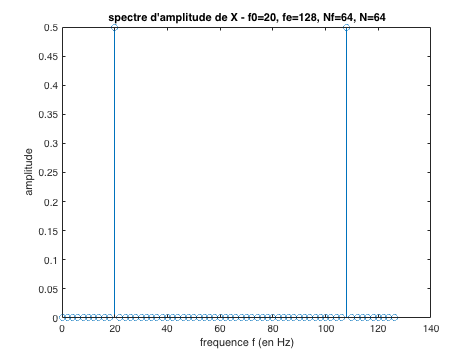

figure
stem(f,abs(X))
title(['spectre d''amplitude de X - f0=',num2str(f0),', fe=',num2str(fe),', Nf=', num2str(Nf),...
    ', N=',num2str(N)])
xlabel('frequence f (en Hz)' )
ylabel('amplitude')

On observe bien 2 pics en f0 (=20Hz, fréquence de la sinusoide) et fe-f0 (=108Hz), qui correspond au pic en -f0 (spectre périodisé avec une période fe).

En revanche, on n'observe pas le noyau de Diriclet (=sinus cardinal périodisé, vu dans la partie théo. dû à la présence de la fenêtre rectangulaire - sinusoide tronquée).

On constate que l'on a un cas particulier où les échantillons pris sont nuls sauf en f0 et fe-f0. C'est pourquoi on n'observe pas la forme caractéristique du sinus cardinal.

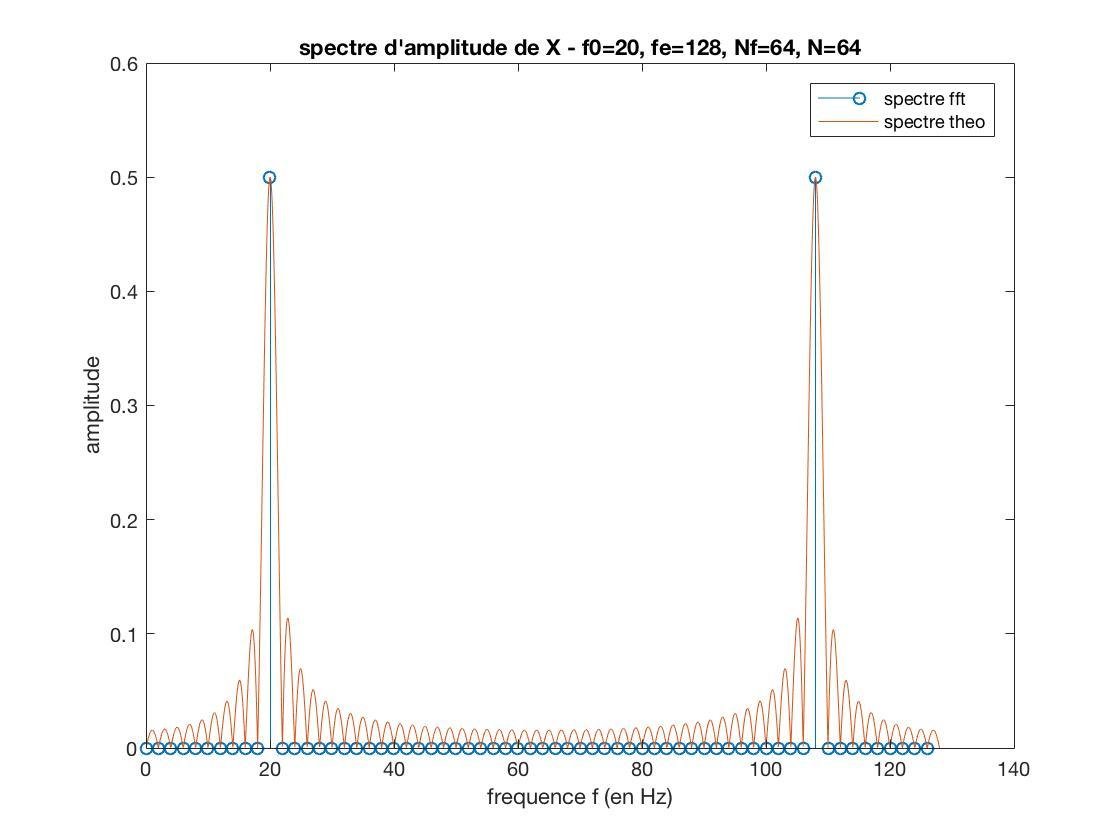

Remarque : avec ces paramètres, la largeur du lobe principal du noyau de Diriclet est égal à 4Hz et celle des lobes secondaires est de 2Hz.

- Affichage du spectre d'amplitude théorique entre -fe/2 et fe/2 (-1 échantillon) :

Xsh=fftshift(X); 

!! Attention, la commande fftshift ne fait pas de fft !!!

Ne pas hésitez à aller voir la documentation de la commande

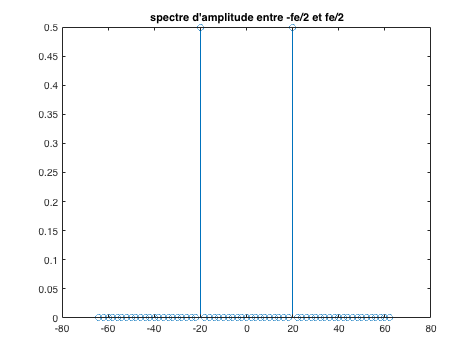

nsh=-Nf/2:Nf/2-1; % Nf doit être un nombre pair
fsh=nsh*fe/Nf;

figure
stem(fsh,abs(Xsh))
title('spectre d''amplitude entre -fe/2 et fe/2')

On observe bien les 2 pics en -f0 et f0, f0 étant la fréquence de la sinusoide.

- Affichage du spectre d'amplitude théorique pour uniquement les fréquences positives (entre 0 et fe/2 (-1 échan)):

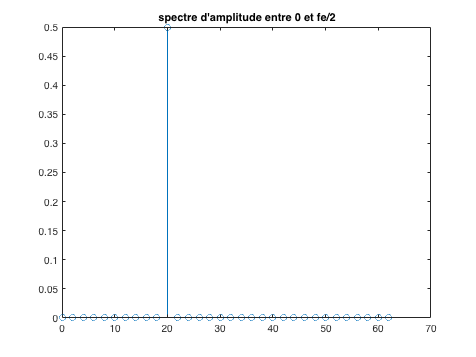

figure
stem(fsh(Nf/2+1:end),abs(Xsh(Nf/2+1:end)))
% stem(f(1:Nf/2),abs(X(1:Nf/2))) % autre solution à partir de X sans fftshift
title('spectre d''amplitude entre 0 et fe/2')

Dans cette partie, on considère les points pour lesquels fsh vaut 0 jusqu'à la fin (end) : la fréquence 0 correspond au (Nf/2+1)ième point de fsh

- Avec une fréquence f0=19Hz

Si on refait la même chose avec f0=19Hz, la forme du résultat est différente, mais on n'observe toujours pas la forme caractéristique du noyau de Diriclet car la fréquence d'échantillonnage du spectre (inverse de la distance entre 2 points du spectre -- pas celle du temps...) est toujours insuffisante.

En jouant sur les paramètres N et Te (ou fe), cela ne change rien car l'intervalle 1/(N.Te)=1/(Nf.Te) entre 2 échantillons est modifié en conséquence. 

## Analyse spectrale avec "zero padding" (Nf>N)

Si on ajoute des valeurs nulles à l'une extrémité ou l'autre (ou les deux) de la sinusoide, on augmente le nombre totale d'échantillons sur lequel est calculé la TF sans pour autant modifier la durée. La résolution fréquentielle 1/(Nf*Te) diminue, donc s'améliore et on voit apparaître plus de "détails" du tracé du spectre.

Remarque : il ne s'agit que de résolution apparente, il n'y a pas de création d'information nouvelle.

2 façons de faire du zéro padding : 1) en ajoutant manuellement des 0 : x=[x zeros(1,64)] ou 2) en utilisant le 2nd paramètre de la fonction fff : X=fft(x,128)

Attention, plus on augmente Nf, plus la charge de calculs est importante !

- Zero padding 1 (ajout de zéros manuellement)

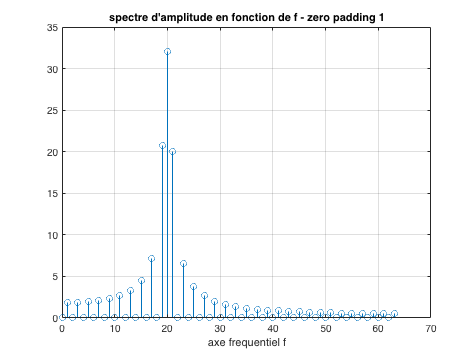

% signal complété par des zéros
Nz=64; % commencer par 64, puis 448 par exemple
x1=[x(:)' zeros(1,Nz)];

% nouveaux axes fréquentiels
Nf=length(x1);
k=0:Nf-1;
f=k*fe/Nf;
X1=fft(x1);
magX1=abs(X1);

figure
stem(f(1:Nf/2),magX1(1:Nf/2)) % axe fréquentiel positif
xlabel('axe frequentiel f')
title('spectre d''amplitude en fonction de f - zero padding 1')
grid on

- Zero padding 2 (fft)

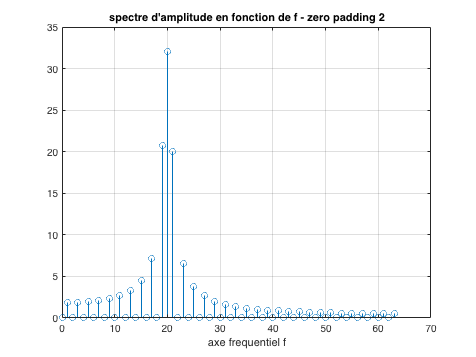

Nf=2*N; % commencer par 2N, puis 8N
k=0:Nf-1;
f=k*fe/Nf;

X=fft(x,Nf);
magX=abs(X);

figure
stem(f(1:Nf/2),magX(1:Nf/2)) % axe fréquentiel positif
xlabel('axe frequentiel f')
title('spectre d''amplitude en fonction de f - zero padding 2')
grid on

## Etude de l'effet du fenêtrage

Le fenêtrage appliqué implicitement au signal jusque là est de type rectangulaire. Il induit dans le domaine fréquentiel l'apparition de noyaux de Diriclet (sinus cardinal périodisé). En effet, la TF de la fenêtre rectangulaire est caractérisée par un lobe principal et des lobes secondaires. Ceci impacte la capacité à pouvoir détecter 2 composantes sinusoidales proches dans un signal.

- Résolution fréquentielle : capacité à pouvoir séparer 2 composantes proches (de même amplitude). Elle est conditionnée par la largeur du lobe principal. Pour la fenêtre rectangulaire, elle est approximativement égale à l'inverse de la durée du signal 1/(N.Te).

- Résolution dynamique : capacité à pouvoir séparer 2 composantes proches et d'amplitudes plus réduites. Les lobes secondaires peuvent "cacher" des pics fréquentiels plus petits ou des lobes secondaires issus de composantes différentes peuvent se superposer pour créer de "faux" pics.

-> L'utilisation d'autres fenêtres s'est imposée rapidement pour obtenir un motif spectral aux caractéristiques différentes. Dans cette partie, on va ainsi étudier 4 autres fenêtres : Bartlett, Blackman, Kaiser et Chebychev.

On va simplement étudier leur TF, sachant que les appliquer à un sinus (multiplication temporelle entre le sinus et la fenêtre) implique simplement un décalage fréquentiel (convolution avec impulsions de Dirac en fréquentiel) - voir commentaires faits précedemment, question g) de l'énoncé et ceux faits en TD.

Remarque : pour effectuer cette étude, il est également possible d'utiliser l'outils wvtool (voir aide de matlab)

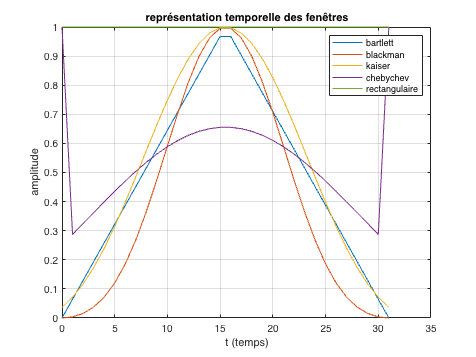

N=32;
k=0:N-1;
Te=1;
fe=1/Te;
t=k*Te;
f1=bartlett(N);
f2=blackman(N);
f3=kaiser(N,5);
f4=chebwin(N,20);
frect=rectwin(N);

figure
plot(t,[f1,f2,f3,f4,frect])
grid on
xlabel('t (temps)')
ylabel('amplitude')
title('représentation temporelle des fenêtres')
legend('bartlett','blackman','kaiser','chebychev','rectangulaire')

Contrairement au cas de la fenêtre rectangulaire, les autres fenêtres doivent être appliquées explicitement au signal étudié, c'est-à-dire que les valeurs du signal doivent être pondérées par les valeurs de la fenêtre, qui doit être de même longueur que le signal (sous Matlab, cela signifie qu'il faut effectuer une multiplication élément par élément entre le vecteur signal étudié et le vecteur fenêtre). Cette étape n'est pas effectuée dans cet exercice pour les raisons déjà indiquées ci-dessus.

Etude des TF des différentes fenêtres :

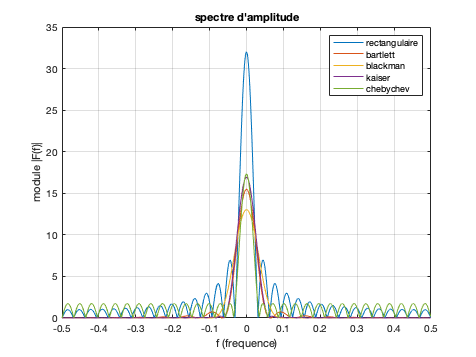


Nf=1024;
n=(-Nf/2:Nf/2-1);
f=n*fe/Nf;

FRect=fftshift(fft(frect,Nf));
F1=fftshift(fft(f1,Nf));
F2=fftshift(fft(f2,Nf));
F3=fftshift(fft(f3,Nf));
F4=fftshift(fft(f4,Nf));

figure
plot(f,abs([FRect F1 F2 F3 F4])) % ou stem puisque le spectre est discret
grid on
xlabel('f (frequence)')
ylabel('module |F(f)|')
title('spectre d''amplitude')
legend('rectangulaire','bartlett','blackman','kaiser','chebychev')

L'affichage du module de la TF en dB permet d'accentuer les caractéristiques

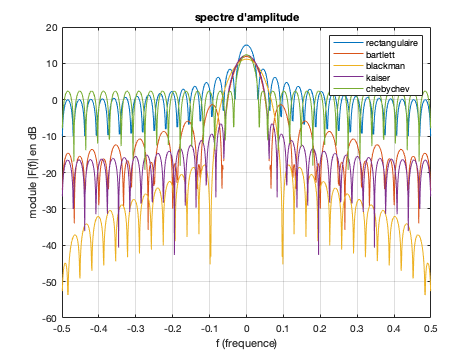

figure
plot(f,10*log10(abs([FRect F1 F2 F3 F4]))) % module en dB
grid on
xlabel('f (frequence)')
ylabel('module |F(f)| en dB')
title('spectre d''amplitude')
legend('rectangulaire','bartlett','blackman','kaiser','chebychev')

Autre façon de faire, en utilisant une échelle log en ordonnée :

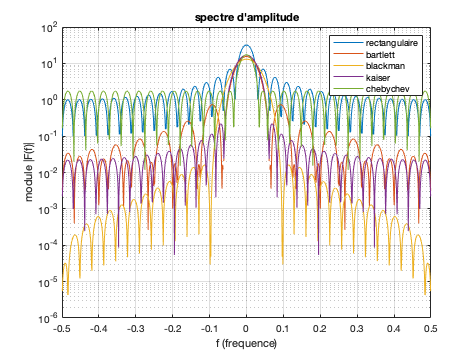

figure
semilogy(f,abs([FRect F1 F2 F3 F4]))
grid on
xlabel('f (frequence)')
ylabel('module |F(f)|')
title('spectre d''amplitude')
legend('rectangulaire','bartlett','blackman','kaiser','chebychev')

Conclusions :

Il s'avère que quelle que soit la fenêtre choisie, le motif spectral correspondant présente toujours des caractéristiques semblables, à savoir un lobe principal accompagné de lobes secondaires. On constate également que plus les lobes secondaires sont de faible hauteur, plus le lobe principal est large. Il y a donc un compromis à établir entre résolution fréquentielle et résolution dynamique.

Au final, c'est en fait la fenêtre rectangulaire qui produit le lobe principal le plus étroit et par conséquent la meilleure résolution fréquentielle (bien que toutes les fenêtres conservent une résolution fréquentielle proportionnelle à l'inverse de la durée du signal).

Une des caractéristiques sur lesquelles on peut jouer est la forme de la décroissance des lobes secondaires. Ainsi, sur les 5 fenêtres retenues, celle de Blackman présente non seulement les lobes secondaires les plus atténués, mais ceux-ci décroissent également bien plus rapidement.

Évidemment, la fenêtre de Blackman produit le lobe principal le plus large. La fenêtre de Chebychev, quant à elle, produit des lobes secondaires de hauteur constante, dont l'atténuation est réglable. En pratique, on aura tout intérêt à tester plusieurs fenêtres avant de fixer son choix.